% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension11    value    uncertainty      uom  
    ___________    _____    ___________    _______

      {'d1' }       55           1         {'CMT'}
      {'d2' }       60           1         {'CMT'}
      {'d3' }       65           1         {'CMT'}
      {'d4' }       70           1         {'CMT'}
      {'d5' }       75           1         {'CMT'}
      {'d6' }       80           1         {'CMT'}
      {'d7' }       85           1         {'CMT'}
      {'d8' }       90           1         {'CMT'}
      {'d9' }       95           1         {'CMT'}
      {'d10'}       98           1         {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1001×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1      {'d10'}     819          1         {'C26'}
      2      {'d10'}     799          1         {'C26'}
      3      {'d10'}     818          1         {'C26'}
      4      {'d10'}     819          1         {'C26'}
      5      {'d10'}     815          1         {'C26'}
      6      {'d10'}     817          1         {'C26'}
      7      {'d10'}     818          1         {'C26'}
      8      {'d10'}     798          1         {'C26'}
      9      {'d10'}     819          1         {'C26'}
     10      {'d10'}     819          1         {'C26'}
     11      {'d10'}     819          1         {'C26'}
     12      {'d10'}     817          1         {'C26'}
     13      {'d10'}     8

tools=readtable("..\data\tools.csv")

tools = 2×3 table
             tool             uncertainty      uom  
    ______________________    ___________    _______

    {'sensore prossimità'}       0.001       {'SEC'}
    {'asta graduata'     }        0.01       {'MTR'}




% unique distance
hd=unique(df2.distance);
ld=length(hd);

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % deviazione standard tempi
d=zeros(ld,1);      % distance from CM

% multiply *2
for i=1:height(df2)
    df2.time(i)=df2.time(i)*2;
end

% calculating mean t in s
for i=1:ld
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time"))./1000);
    dtm(i)=std(table2array(df2(df2.distance==string(hd(i)),"time"))./1000);
    d(i)=df1(df1.)
end

cat(2,string(hd),tm,dtm)

ans = 10×3 string array
    "d1"     "3.1408"    "0.023539"
    "d10"    "1.6275"    "0.016542"
    "d2"     "2.0203"    "0.019995"
    "d3"     "1.7548"    "0.047654"
    "d4"     "1.5974"    "0.010466"
    "d5"     "1.5833"    "0.020015"
    "d6"     "1.5604"    "0.01231" 
    "d7"     "1.5321"    "0.019243"
    "d8"     "1.5712"    "0.019175"
    "d9"     "1.5939"    "0.010867"


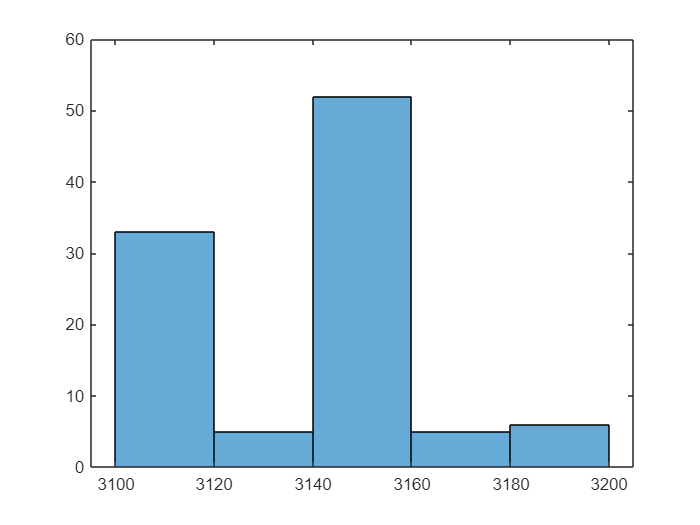


% histogram

histogram(table2array(df2(df2.distance==string(hd(1)),"time")))

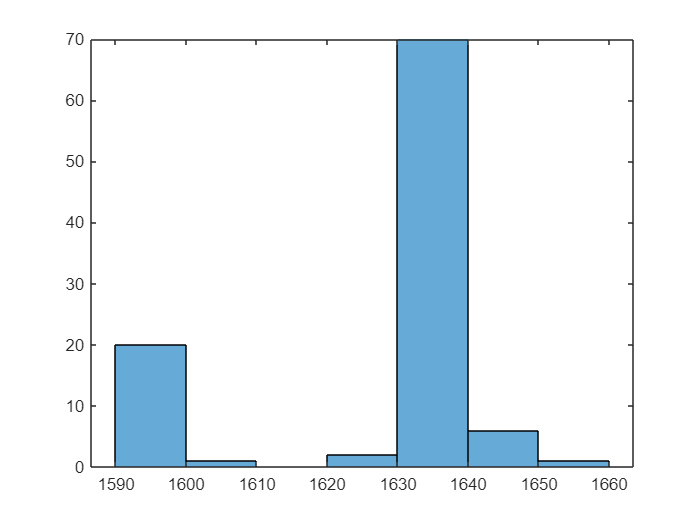

histogram(table2array(df2(df2.distance==string(hd(2)),"time")))

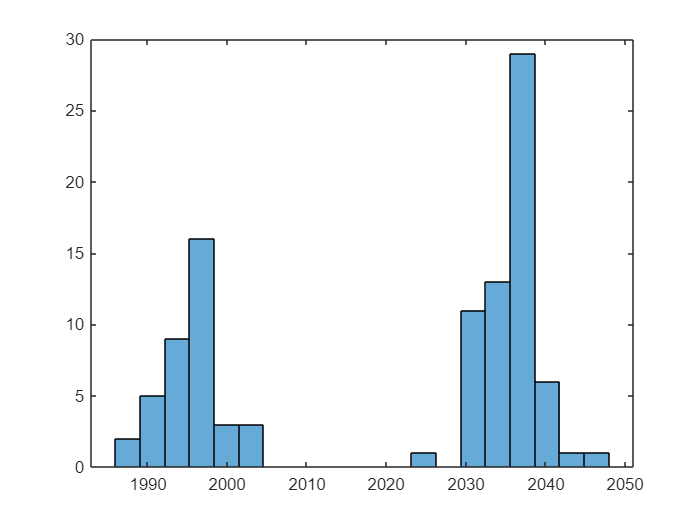

histogram(table2array(df2(df2.distance==string(hd(3)),"time")),20)

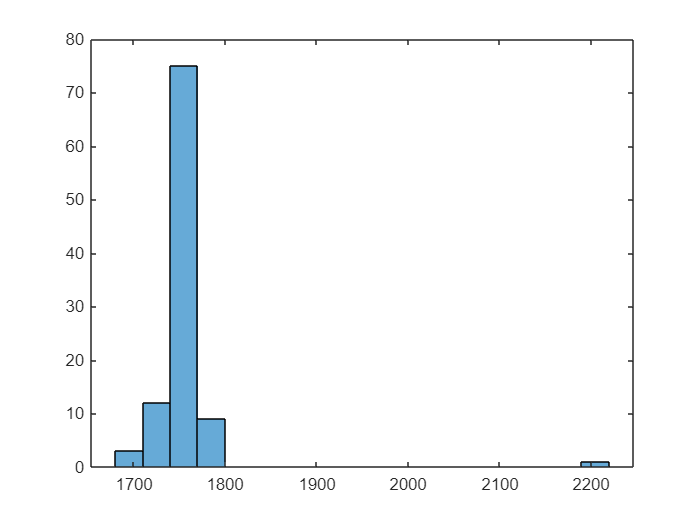

histogram(table2array(df2(df2.distance==string(hd(4)),"time")))

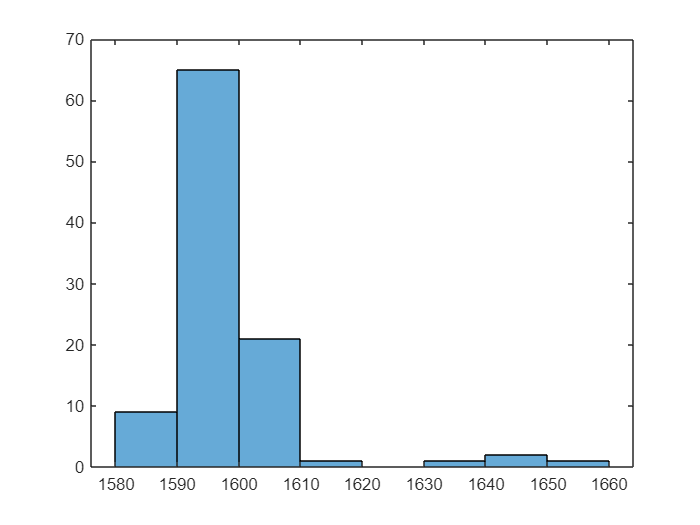

histogram(table2array(df2(df2.distance==string(hd(5)),"time")))

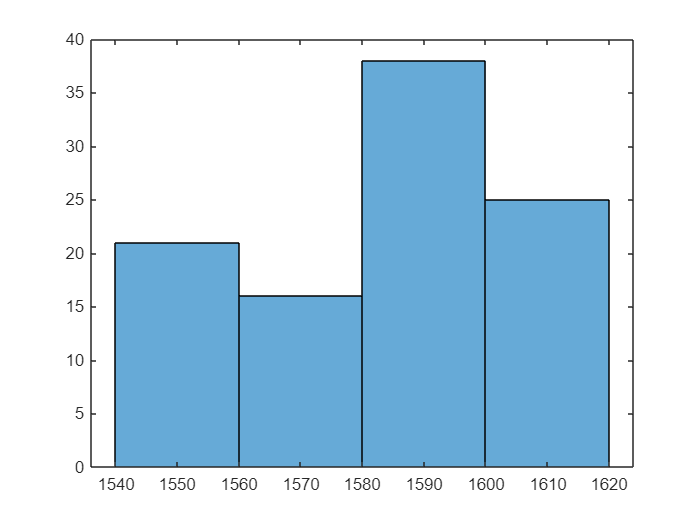

histogram(table2array(df2(df2.distance==string(hd(6)),"time")))



% df2(df2.distance=="d1","time") % sostituire "d1" con gli elementi degli array
% mean(table2array(df2(df2.distance=="d1","time")))

% exporting csv
% writetable(array2table(namearray,'VariableNames',{'acceleration','uncertainty','uom','relative_error'}),'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
% saveas(nameplot,'..\img\filename.png');

% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);